% Question 1. Record the utterance "My name is "your-name" 
% in your own voice with a sampling frequency of 16 kHz. 
% Normalize the speech data to lie between -1 and +1.

% Short time analysis code
clear all
close all
clc

% recording audio 
fs = 16000;
NumSeconds = 5;
NumBits_quant = 16;
Num_channels = 1; % mono 1 channel, 2 for stereo


recorder = audiorecorder(fs, NumBits_quant, Num_channels);
disp('start speaking')

start speaking


recordblocking(recorder,NumSeconds);
disp('stop speaking')

stop speaking


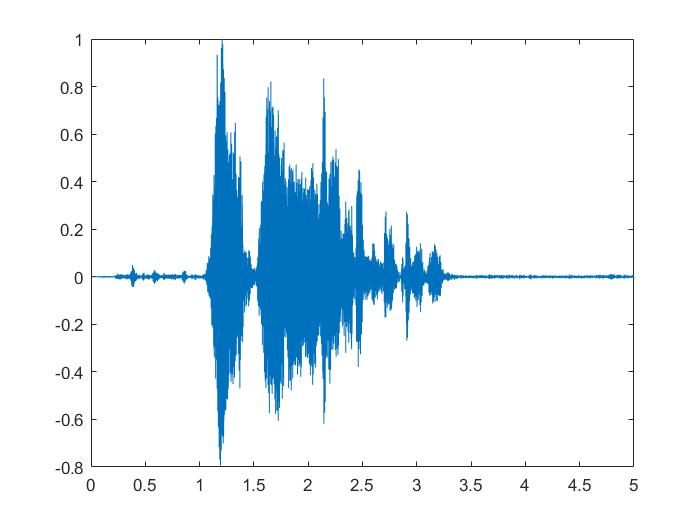

Speech_data = getaudiodata(recorder);

Speech_data = Speech_data / max(abs(Speech_data));

% playing the audio on speaker
sound(Speech_data, fs)

% writing the audio to a file
audiowrite('abhishek_record.wav',Speech_data,fs);

% read from the audio file
[speech, fs] = audioread('abhishek_record.wav');
t= 0:(1/fs):(length(speech)-1)/fs;
figure;plot(t,speech)

sound(speech, fs)

% normalize the speech
speech_att = speech*0.5;
speech_amp = speech*2;
sound(speech_att, fs);

sound(speech_amp, fs);


